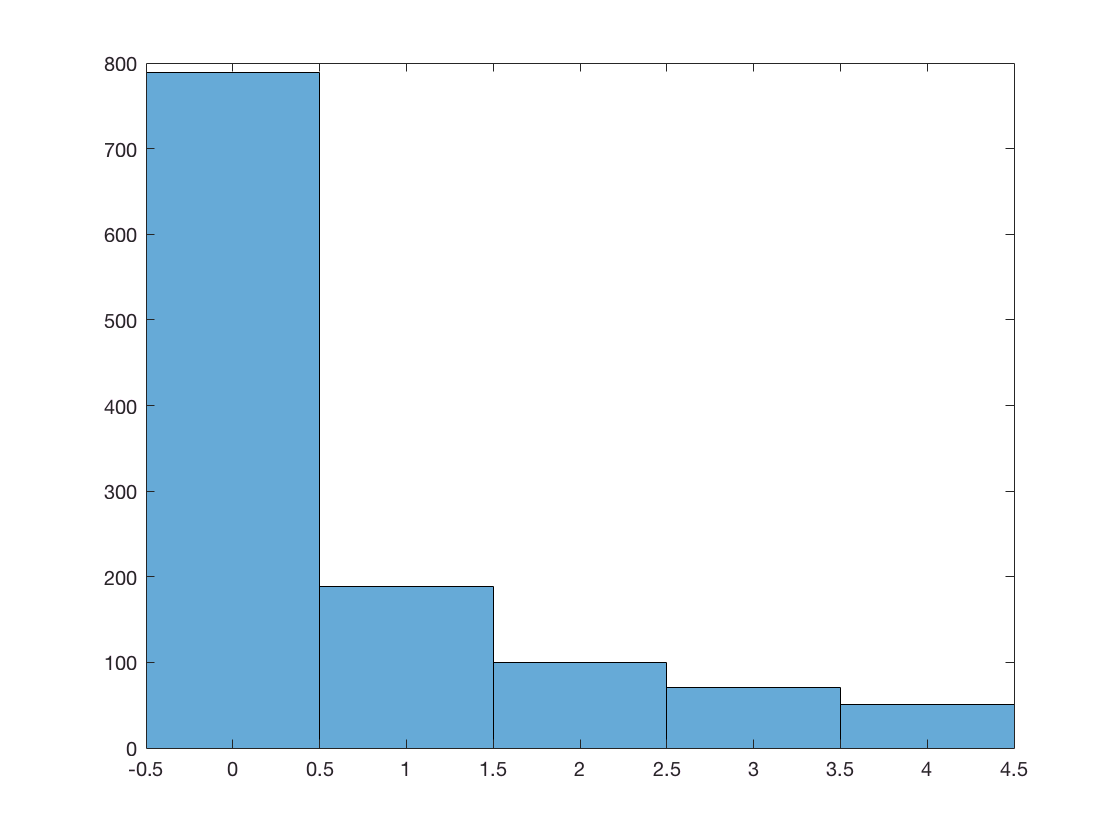

times = importdata('/Users/tyler/code/seng462/docs/data/quoteserver-times/times.csv', ',');

% Remove network delay to isolate distribution of qs delay
times = floor(times);

histogram(times, [-0.5:4.5])

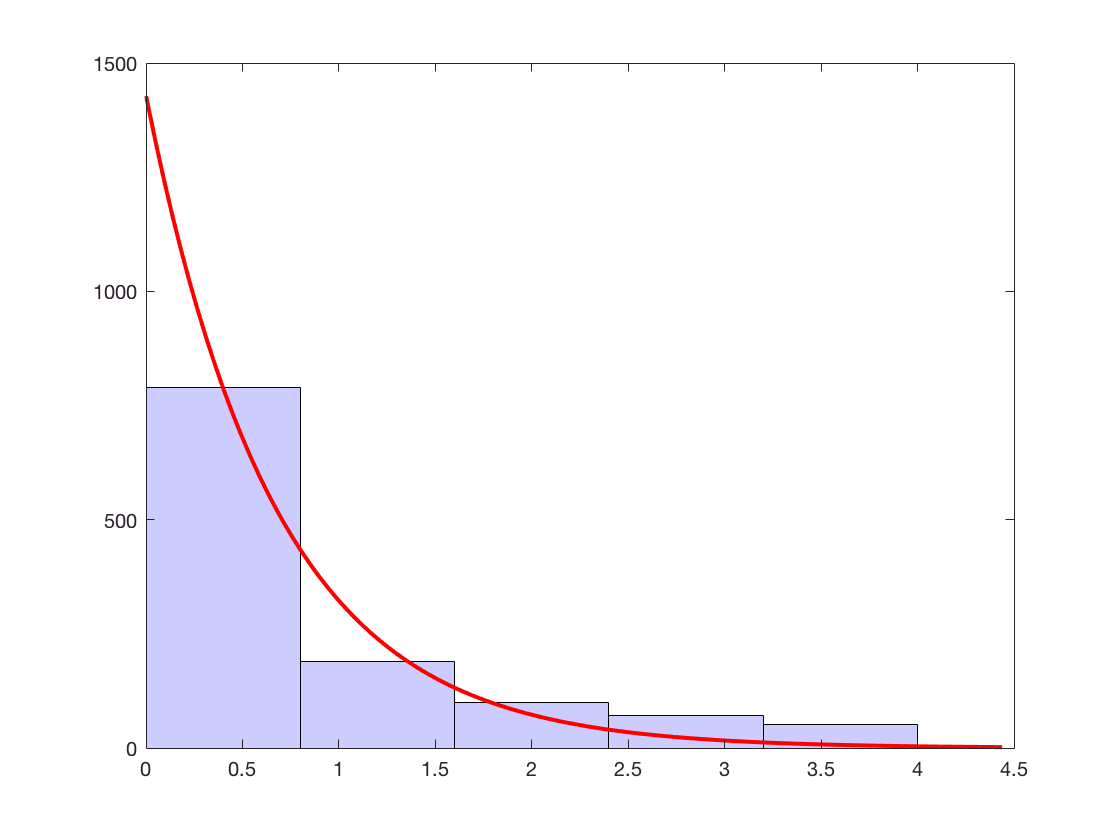


hexp = histfit(times, 5, 'exponential');
hexp(1).FaceColor = [.8 .8 1];

expdist = fitdist(times, 'exponential');
expdist.mu

ans = 0.6717


[~, p, stats] = chi2gof(times, ...
                        'Ctrs', [0:4], ...
                        'CDF', expdist)

p = 8.8905e-128

stats =     chi2stat: 591.0255
          df: 3
       edges: [-0.5000 0.5000 1.5000 2.5000 3.5000 4.5000]
           O: [789 189 100 71 51]
           E: [629.9865 441.3981 99.5951 22.4722 6.5480]
